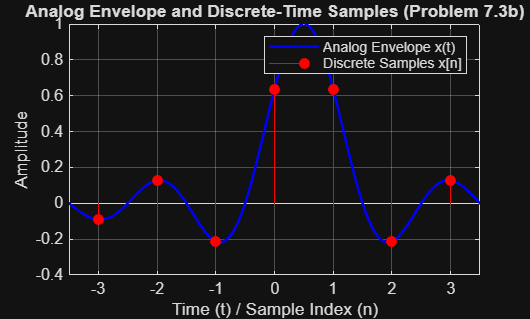

% 7.3)

% Define the analytical function for the envelope
sinc_envelope = @(t) sin(pi*(t - 0.5)) ./ (pi*(t - 0.5));

% --- 1. Plot the Analog Envelope (Continuous Line) ---
% Define a fine time vector (t_cont) for the continuous plot
t_cont = -4:0.01:4; 
x_cont = sinc_envelope(t_cont);

figure;
plot(t_cont, x_cont, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Analog Envelope x(t)');
hold on; 

% --- 2. Plot the Discrete-Time Signal (Stem Plot) ---
% Define the discrete index vector (n) for the samples
n = -3:3; 
x_n = sinc_envelope(n);

% Plot the discrete samples using stem
stem(n, x_n, 'r', 'filled', 'MarkerSize', 6, 'DisplayName', 'Discrete Samples x[n]');
hold off;

% --- 3. Labeling and Aesthetics ---
title('Analog Envelope and Discrete-Time Samples (Problem 7.3b)');
xlabel('Time (t) / Sample Index (n)');
ylabel('Amplitude');
legend('show', 'Location', 'NorthEast');
xlim([-3.5 3.5]);
grid on;